# Example of Functional Sensor to Segment Calibration using Xsens and Magnetic-Free-Quaternion-Based data

S. A. Salinas, M. Berjis, K. Grolinger, and A. L. Trejos, Estimating Thorax and Shoulder Motion Using Magnetic-Free Quaternion-Based Functional Sensor-to-Segment Calibration, International Conference on Rehabilitation Robotics (ICORR), Chicago, USA, May 2025.

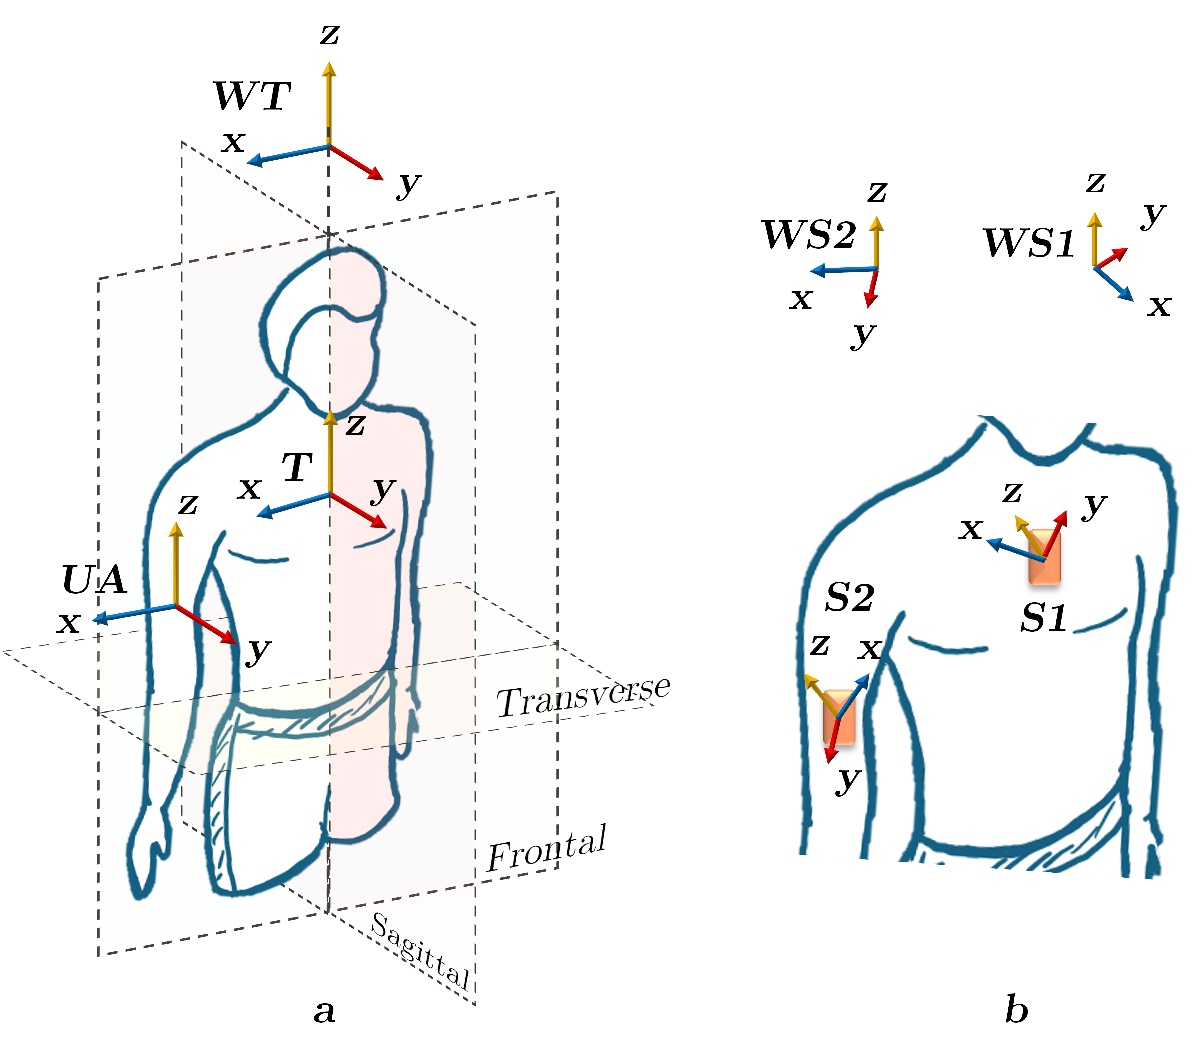

The calibration is used in this example for thorax and shoulder orientations. 

The thorax is the first segment of interest with one inertial sensor attached to it. As shown in the figure, the coordinate system (T), linked to the thorax, changes its orientation as a function of the thorax motion. Its z axis is the inferior--superior axis perpendicular to the transverse plane, the y axis is the anterior--posterior axis perpendicular to frontal plane, and the x axis is the medio--lateral axis perpendicular to the sagittal plane. The orientation of T is measured with respect to a global reference coordinate system of the body (WT). This reference frame corresponds to the sagittal, frontal, and transverse planes when the participant is in an initial N-pose. The vertical axis pointing up is defined as the positive z axis, the sagittal axis from the back to the front of the body is defined as the positive y axis, and the frontal axis from left to right is defined as the positive x axis. 

The IMU attached to the thorax is represented by a box with a reference coordinate system (S1). The orientation of S1 is measured by this IMU with respect to its own global reference coordinate system (WS1). 

The upper arm is the second segment. The coordinate system (UA) linked to the upper arm changes its orientation as a function of the upper arm motion. Its z axis corresponds to the shoulder internal--external rotation axis, the y axis coincides with the shoulder abduction--adduction axis, and the x axis with the shoulder flexion--extension axis. 

The IMU attached to the upper arm is represented by a box with a reference coordinate system (S2). The orientation of S2 is measured by this IMU with respect to its own global reference coordinate system (WS2). It is important to note that WS1 and WS2 have different orientations. However, the constant rotation between the global reference coordinate systems of the two inertial sensors is a rotation about their z axes.  

Two set of sensors were used, the commercial Xsens and a prototype based on the BNO055 sensor. Orientation data were simultaneously collected by both systems while the participant stood in a static N-pose for ten seconds, followed by ten functional movement repetitions of the thorax or upper arm. The thorax movements were forward flexions and lateral flexion--extension; whereas, the upper arm movements were consequences of shoulder flexion--extension and shoulder abduction--adduction.

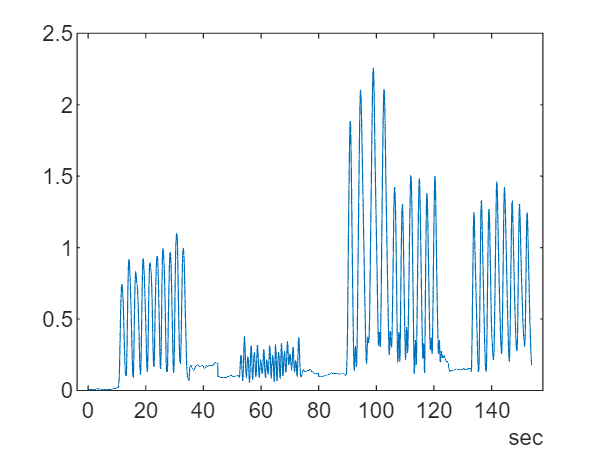

clear 
close all
load("qAll.mat")
plot(qs.Time, dist(qs{:,"Var1_qS3"},qs{1,"Var1_qS3"}))

### Thorax


intervX = {timerange(seconds(0),seconds(7));  % X axis of body    Squats           
        timerange(seconds(7),seconds(35));
        };
intervY = {timerange(seconds(46),seconds(51));    % Y axis of body   Sides
        timerange(seconds(51),seconds(75));
        };
axisMov = { {"x", "y"}, ... %Xsens
            {"x", "y"}};%IMU
[BqS, WBqWS] = ...
            S2SCalibT(qs(:,["Var1_qX1","Var1_qS1"]), intervX, intervY, axisMov)

BqS = 1×2 quaternion array
     0.56326 - 0.39559i - 0.47382j - 0.54931k    -0.59772 + 0.42079i + 0.34868j + 0.58659k


WBqWS = 1×2 quaternion array
     0.67237 +       0i +       0j - 0.74022k    -0.98965 +       0i +       0j - 0.14349k



WBqT = timetable(qs.Time);
WBqT{:,1:2} = WBqWS .* qs{:,["Var1_qX1","Var1_qS1"]} .* conj(BqS);

TqS1 = BqS;
WBqW1 = WBqWS;

### Upper Arm

intervY = {timerange(seconds(129),seconds(131));  % Y axis of body    Abd
        timerange(seconds(131),seconds(153.95));
        };
intervX = {timerange(seconds(85),seconds(87));    % X axis of body   FE
        timerange(seconds(105),seconds(122)); 
        };
axisMov = { {"x", "-y"}, ... %Xsens
            {"-x", "y"}};%IMU
[UAqS2, W1qW2] = S2SCalibUA( qs(:,["Var1_qX3","Var1_qS3"]), intervX, intervY, axisMov,...
                                        qs(:,["Var1_qX1","Var1_qS1"]), TqS1, WBqW1)

UAqS2 = 1×2 quaternion array
    -0.11454 - 0.70116i + 0.04036j - 0.70259k    -0.60006 - 0.33448i + 0.65953j - 0.30506k


W1qW2 = 1×2 quaternion array
      0.99939 +        0i +        0j - 0.034899k      0.62592 +        0i +        0j -  0.77988k



TqUA = timetable(qs.Time);
TqUA{:,1:2} = TqS1 .* conj(qs{:,["Var1_qX1","Var1_qS1"]}) .* W1qW2 .* ...
                           qs{:,["Var1_qX3","Var1_qS3"]}  .* conj(UAqS2);